
cam = webcam("USB2.0 HD UVC WebCam", "resolution", "1280x720")

cam =   webcam with properties:

                     Name: 'USB2.0 HD UVC WebCam'
     AvailableResolutions: {'1280x720'  '800x600'  '640x480'  '352x288'  '320x240'  '176x144'  '160x120'}
               Resolution: '1280x720'
             WhiteBalance: 4600
                 Exposure: -6
               Brightness: 0
                    Gamma: 100
                 Contrast: 32
               Saturation: 64
                      Hue: 0
                Sharpness: 3
    BacklightCompensation: 1
                     Gain: 0
             ExposureMode: 'auto'
         WhiteBalanceMode: 'auto'


image = snapshot(cam)

image = 720×1280×3 uint8 array
image(:,:,1) =

   165   167   169   169   169   171   171   171   168   169   167   167   164   164   162   162   160   161   159   157   156   156   156   157   153   150   146   144   140   139   137   135   132   132   132   132   132   132   132   132   132   132   131   129   129   131   132   133   134   136   136   136   134   132   130   129   128   128   130   130   130   131   134   138   137   141   141   144   142   140   135   133   132   131   131   131   130   130   130   128   129   127   125   124   124   124   124   124   124   124   125   125   128   128   127   126   127   125   138   138   133   139   140   137   151   149   155   162   162   167   171   168   155   169   173   181   182   176   177   179   181   183   184   183   182   181   183   185   184   183   182   182   179   180   179   179   181   181   182   183   185   185   184   184   174   182   184   180   178   183   180   172   184   173   174   177   171   174   17

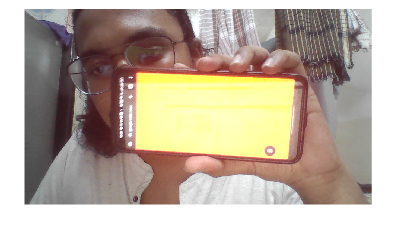

imshow(image)


r = image(:,:,1);
g = image(:,:,2);
b = image(:,:,3);

%red
sum_elements_matrix_red = sum(r,"all");
size_r = size(r);
total_r = size_r(1)*size_r(2);
mean_r = sum_elements_matrix_red/total_r

mean_r = 161.6793


%green
sum_elements_matrix_green = sum(g,"all");
size_g = size(g);
total_g = size_g(1)*size_g(2);
mean_g = sum_elements_matrix_green/total_g

mean_g = 144.3249


%blue
sum_elements_matrix_blue = sum(b,"all");
size_b = size(b);
total_b = size_b(1)*size_b(2);
mean_b = sum_elements_matrix_blue/total_b

mean_b = 124.7355


if mean_r > mean_g && mean_r > mean_b
    disp("the prominent colour is red")
elseif mean_g > mean_r && mean_g > mean_b
    disp("the prominent colour is green")
else 
    disp("the prominent colour is blue")
end

the prominent colour is red


clear ; 
close all; 
clc;
imaqreset;
